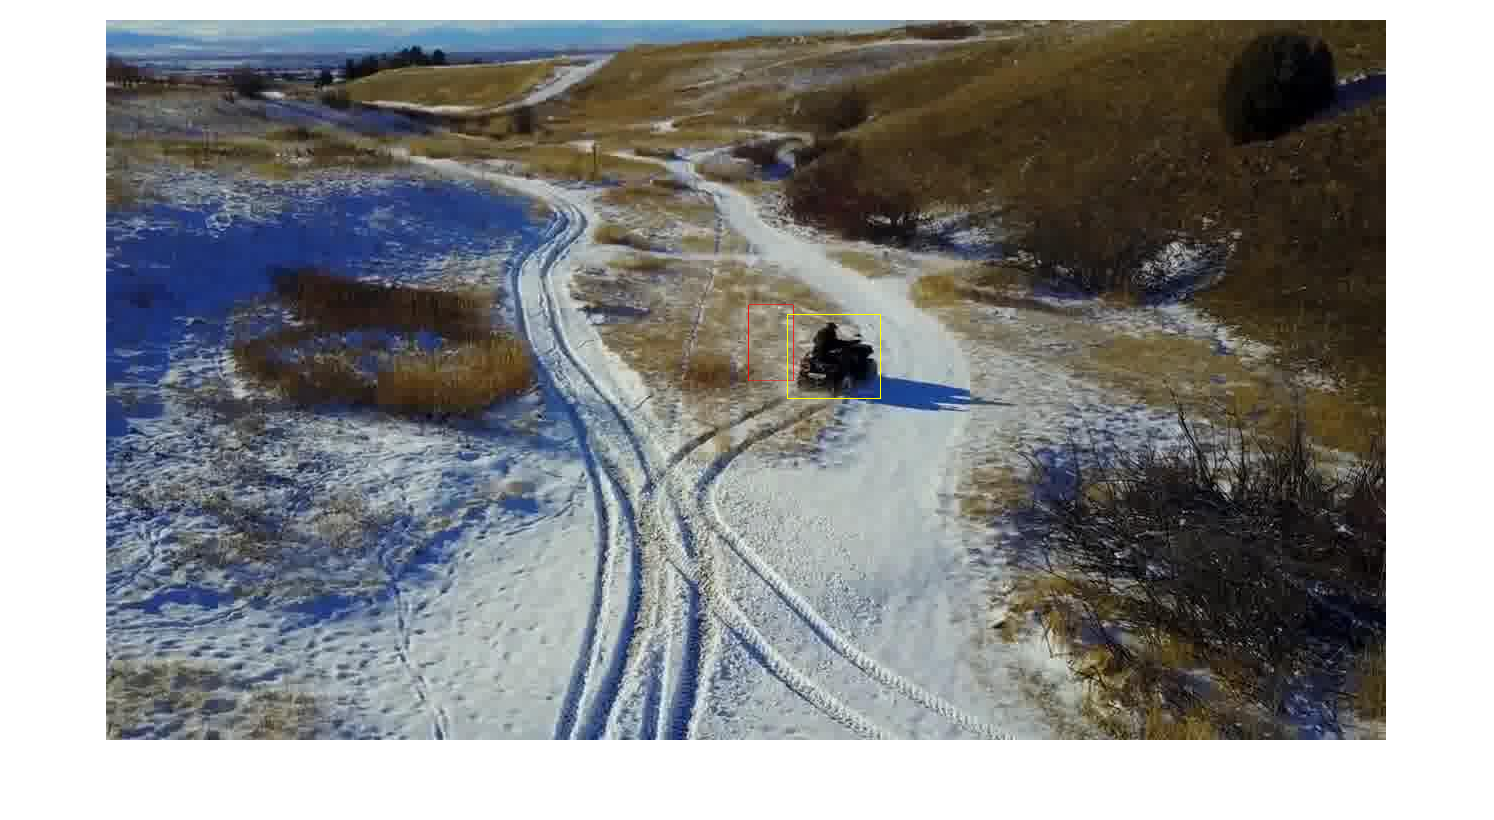

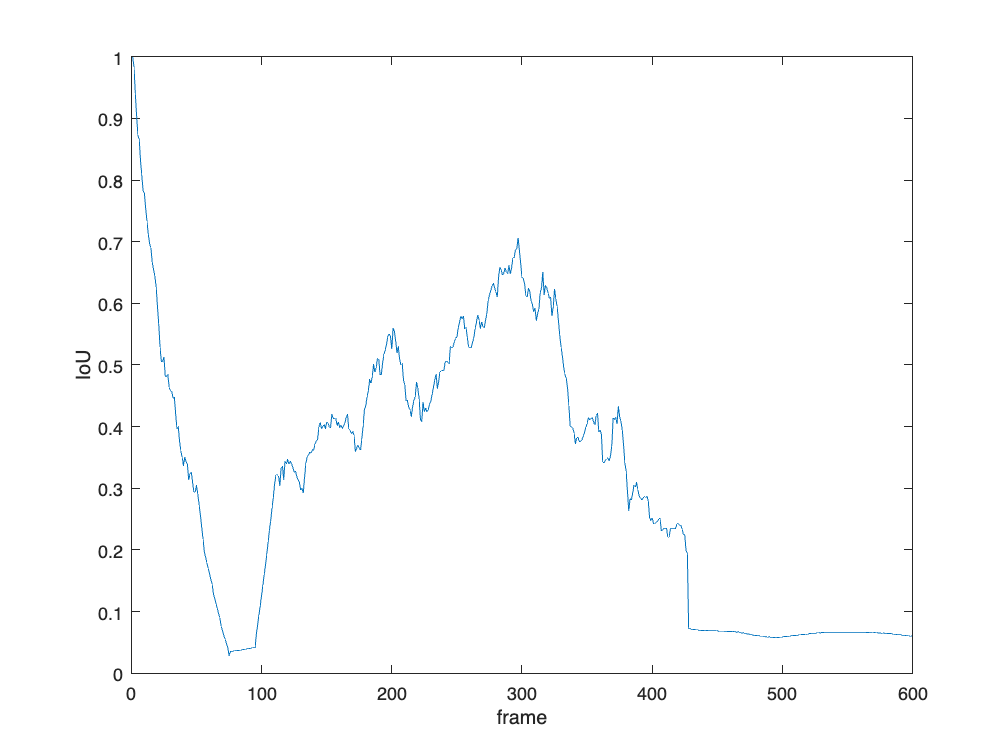

First frame with total loss: -1
Number of frames with good overlap ratio: 135


close all
objects = ["Drone3"];
debug_mode = false;

Execute_Algorithm(objects, "SS", debug_mode);

function Execute_Algorithm(objects, method, debug_mode)
    n_objects = size(objects,2);
    for n = 1:n_objects
        object = objects(n);
        BB = importdata("./TinyTLP/" + object + "/groundtruth_rect.txt");
        Idir = dir("./TinyTLP/" + object + "/img/*.jpg");
        initBB = [BB(1,2), BB(1,3), BB(1,4), BB(1,5)];
        nf = size(Idir);
        filename = horzcat(Idir(1).folder,'/',Idir(1).name);
        frame = imread(filename);
        frame_size = [size(frame, 1), size(frame, 2)];
        currentBB = initBB;
        current_area = (initBB(3) * initBB(4)) / 2;
        first_frame_with_total_loss = -1;
        frames_with_good_ratio = 0;
        IoU_ratios = zeros(nf);
        figure
        for i = 1:nf
            objectToTrack = imcrop(frame, currentBB);
            filename = horzcat(Idir(i).folder,'/',Idir(i).name);
            frame = imread(filename);
            
            if (method == "SS")
                [m_kp_obj, m_kp_esc] = Get_Matched_Points(objectToTrack, frame);
            elseif (method == "SIFT")
                [m_kp_obj, m_kp_esc] = Get_Matched_SIFT_Points(objectToTrack, frame);
            else
                [m_kp_obj, m_kp_esc] = Get_Matched_SURF_Points(objectToTrack, frame);
            end
            
            [T, ~, status] = estimateGeometricTransform2D(m_kp_obj, m_kp_esc, "affine");
            if (status == 0)
                [f, c] = size(rgb2gray(objectToTrack));
                points = [1,1; 1,f; c,f; c,1];
                transformed_points = transformPointsForward(T,points);
                transformed_rectangle = Calculate_Rectangle(transformed_points);
                if (Is_Valid_Rectangle(transformed_rectangle, frame_size))
                    new_area = (transformed_rectangle(3) * transformed_rectangle(4)) / 2;
                    area_ratio = new_area / current_area;
                    if (area_ratio < 0.9)
                        if (debug_mode)
                            fprintf('Ratio too small! Ignoring new bounding box, ratio = %d\n', area_ratio);
                        end
                    elseif (area_ratio > 1.1)
                        if (debug_mode)
                            fprintf('Ratio too big! Ignoring new bounding box, ratio = %d\n', area_ratio);
                        end               
                    else
                        currentBB = transformed_rectangle;
                        current_area = new_area;
                    end
                end
            else
                if (status == 1)
                    if (debug_mode)
                        fprintf('matchedPoints1 and matchedPoints2 inputs do not contain enough points\n');
                    end
                    
                else
                    if (debug_mode)
                        fprintf('Not enough inliers found\n');
                    end
                end
            end
            imshow(frame);
            hold on
            rectangle('Position', currentBB,'EdgeColor','red');
            rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
            hold off
            drawnow
        
            overlap_ratio = bboxOverlapRatio(currentBB,BB(i,2:5));
            IoU_ratios(i) = overlap_ratio;
            if (overlap_ratio == 0 && first_frame_with_total_loss == -1)
                first_frame_with_total_loss = i;
            end
            if (overlap_ratio > 0.5)
                frames_with_good_ratio = frames_with_good_ratio + 1;
            end
        end
        figure
        plot(1:600, IoU_ratios)
        ylim([0, 1])
        xlabel('frame')
        ylabel('IoU');
        fprintf('First frame with total loss: %d\n', first_frame_with_total_loss);
        fprintf('Number of frames with good overlap ratio: %d\n', frames_with_good_ratio);
    end
end

function [rectangle] = Calculate_Rectangle(points)
    [upper_left, upper_right, bottom_left, bottom_right] = Get_Corner_Points(points);

    y = (upper_left(2) + upper_right(2)) / 2;
    x = (upper_left(1) + bottom_left(1)) / 2;
    w = (upper_right(1) + bottom_right(1)) / 2 - x;
    h = (bottom_left(2) + bottom_right(2)) / 2 - y;

    rectangle = [x y w h];
end

function valid = Is_Valid_Rectangle(rectangle, frame_size)
    x = rectangle(1);
    y = rectangle(2);
    w = rectangle(3);
    h = rectangle(4);
    frame_height = frame_size(1);
    frame_width = frame_size(2);
    valid = (x >= 1) && (y >= 1) && (x + w - 1 <= frame_width) && (y + h - 1 <= frame_height);
end

function [upper_left, upper_right, bottom_left, bottom_right] = Get_Corner_Points(points)
    sorted_points = sortrows(points, 1);
    leftmost = sorted_points(1:2, :);
    rightmost = sorted_points(3:4, :);
    sorted_left = sortrows(leftmost, 2);
    sorted_right = sortrows(rightmost, 2);

    upper_left = sorted_left(1, :);
    bottom_left = sorted_left(2, :);
    upper_right = sorted_right(1, :);
    bottom_right = sorted_right(2, :);
end

function [m_kp_obj, m_kp_esc] = Get_Matched_SIFT_Points(objectToTrack, frame)
    im_obj = rgb2gray(objectToTrack);
    im_esc = rgb2gray(frame);
    kp_obj = detectSIFTFeatures(im_obj);
    kp_obj = selectStrongest(kp_obj, 500);
    kp_esc = detectSIFTFeatures(im_esc);
    kp_esc = selectStrongest(kp_esc, 500);
    [feat_obj,kp_obj] = extractFeatures(im_obj, kp_obj, 'Method','SIFT');
    [feat_esc,kp_esc] = extractFeatures(im_esc, kp_esc, 'Method','SIFT');
    pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',10);
    m_kp_obj = kp_obj(pairs(:,1),:);
    m_kp_esc = kp_esc(pairs(:,2),:);
end

function [m_kp_obj, m_kp_esc] = Get_Matched_SURF_Points(objectToTrack, frame)
    im_obj = rgb2gray(objectToTrack);
    im_esc = rgb2gray(frame);
    kp_obj = detectSURFFeatures(im_obj);
    kp_obj = selectStrongest(kp_obj, 500);
    kp_esc = detectSURFFeatures(im_esc);
    kp_esc = selectStrongest(kp_esc, 500);
    [feat_obj,kp_obj] = extractFeatures(im_obj, kp_obj, 'Method','SURF');
    [feat_esc,kp_esc] = extractFeatures(im_esc, kp_esc, 'Method','SURF');
    pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',10);
    m_kp_obj = kp_obj(pairs(:,1),:);
    m_kp_esc = kp_esc(pairs(:,2),:);
end

function [m_kp_obj, m_kp_esc] = Get_Matched_Points(objectToTrack, frame)
    [sift_m_kp_obj, sift_m_kp_esc] = Get_Matched_SIFT_Points(objectToTrack, frame);
    [surf_m_kp_obj, surf_m_kp_esc] = Get_Matched_SURF_Points(objectToTrack, frame);

    m_kp_obj = [sift_m_kp_obj.Location; surf_m_kp_obj.Location];
    m_kp_esc = [sift_m_kp_esc.Location; surf_m_kp_esc.Location];
end